% Vbat=50;
% Vdc=800;
% f=100e3;
% Lk=100e-6;
% n=4;功率归一化，所以以上参数暂时注释
clearvars

Lk=1;
n=101;%傅里叶展开次数，奇数次展开
m=81;%迭代式中移相比=m/100，m表示占比的整数值
D=100;%迭代式中占空比=D/100，D表示占空比的整数值
Po=zeros(n);%二维零矩阵
po(:,:,1)=Po;%赋值第一层
%po=Po(1:n,1:m); 
%D=0.3;%单独设定占空比，对应一条曲线
for i=1:2:n
    for D=1:100
        for beta=1:m
            po(beta,D,i+2)=po(beta,D,i)+1/i^3/Lk*cos(i*(0.5-D/100)*pi)...
            *sin(i*(beta*pi/100+(0.5-D/100)*pi));
        end
    end
end
[x,y]=meshgrid(0:1:100)

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14   

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3   

z1=po(:,:,101)

z1 =     0.0384    0.0756    0.1112    0.1453    0.1779    0.2089    0.2384    0.2663    0.2926    0.3174    0.3407    0.3624    0.3825    0.4011    0.4182    0.4337    0.4477    0.4601    0.4709    0.4802    0.4880    0.4942    0.4988    0.5019    0.5035    0.5035    0.5019    0.4988    0.4942    0.4880    0.4802    0.4709    0.4601    0.4477    0.4337    0.4182    0.4011    0.3825    0.3624    0.3407    0.3174    0.2926    0.2663    0.2384    0.2089    0.1779    0.1453    0.1112    0.0756    0.0384
    0.0380    0.0760    0.1124    0.1473    0.1806    0.2124    0.2426    0.2713    0.2984    0.3240    0.3480    0.3705    0.3915    0.4108    0.4287    0.4449    0.4597    0.4728    0.4845    0.4945    0.5031    0.5100    0.5155    0.5194    0.5217    0.5225    0.5217    0.5194    0.5155    0.5100    0.5031    0.4945    0.4845    0.4728    0.4597    0.4449    0.4287    0.4108    0.3915    0.3705    0.3480    0.3240    0.2984    0.2713    0.2426    0.2124    0.1806    0.1473    0.1124    

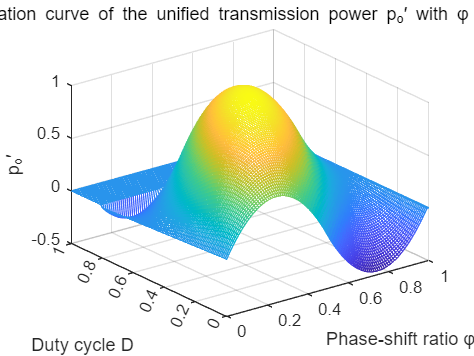

mesh(x,y,z1)
%axis([0,80,0,100,0,1])
hold on
xlabel('Phase-shift ratio φ') %设置横坐标轴
ylabel('Duty cycle D') %设置纵坐标轴
zlabel('p_o′')
title('Relation curve of the unified transmission power p_o′ with φ and D')
xticks([0 20 40 60 80 100])
xticklabels({0 0.2 0.4 0.6 0.8 1})
yticks([0 20 40 60 80 100])
yticklabels({0 0.2 0.4 0.6 0.8 1})

%hold on
%grid on
% y3=po(n,:,2);%D=0.5
% plot(x,y3,'red')
% hold on
% y4=po(n,:,3);%D=0.75
% plot(x,y4,'black')
% hold on
% D=0.4;
% for i=1:2:n
%     for beta=1:m
%             po(i+2,beta)=po(i,beta)+1/i^3/Lk*cos(i*(0.5-D)*pi)...
%             *sin(i*(beta*pi/100+(0.5-D)*pi));
%     end
% end
% y2=po(n,:);
% plot(x,y2,'red')
% % xlabel('beta*100') %设置横坐标轴
% % ylabel('normalizedP') %设置纵坐标轴
% hold on
% 
% D=0.5;
% for i=1:2:n
%     for beta=1:m
%             po(i+2,beta)=po(i,beta)+1/i^3/Lk*cos(i*(0.5-D)*pi)...
%             *sin(i*(beta*pi/100+(0.5-D)*pi));
%     end
% end
% y3=po(n,:);
% plot(x,y3,'black')
% % xlabel('beta*100') %设置横坐标轴
% % ylabel('normalizedP') %设置纵坐标轴
% hold on

